# correlazione e p-value tra rapine e percezione di insicurezza

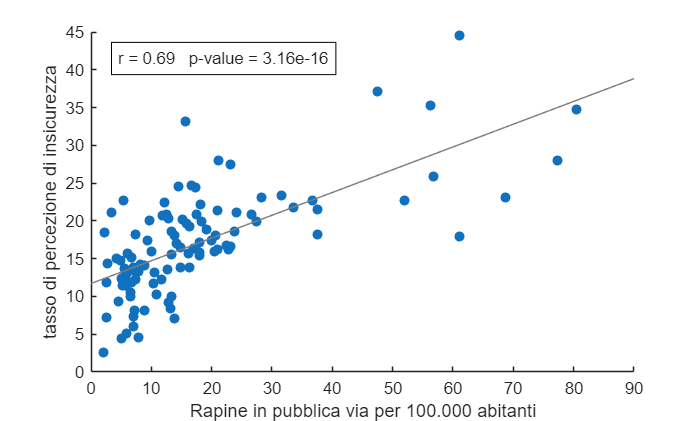


%%!git clone https://github.com/IlSole24ORE/QDV2025.git

nomecartella='QDV2025';
nomefile='20251201_QDV2025_001.csv';
X=readtable([nomecartella filesep nomefile]);
Y2=pivot(X(1:end-1,:),'Rows',"DENOMINAZIONECORRENTE","Columns",'INDICATORE','DataVariable','VALORE','Method','none','RowLabelPlacement','rownames');
Rap=Y2.("Rapine in pubblica via"); %espresso per ogni 100.000 abitanti
Perc=Y2.("Percezione di insicurezza");
Nomiprovince=string(Y2.Properties.RowNames);
[r,pval]=corr(Rap,Perc);
s = scatter(Rap, Perc, 36, 'filled');

%aggiungo i nomi delle province in una categoria nuova
s.UserData.Provincia = Nomiprovince;  
%aggiungo una riga aggiuntiva alle etichette di ciascun data point
%contenente la rispettiva provincia
s.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow("Provincia", s.UserData.Provincia);
xlabel("Rapine in pubblica via per 100.000 abitanti")
ylabel("tasso di percezione di insicurezza")
lsline %%aggiunge in automatico la retta dei minimi quadrati

%%aggiunge una finestra di testo con il valore di r e del p-value
txt = sprintf('r = %.2f   p-value = %.3g', r, pval);
ax = gca;
xl = ax.XLim; 
yl = ax.YLim;
xpos = xl(1) + 0.05*(xl(2)-xl(1));  
ypos = yl(2) - 0.05*(yl(2)-yl(1));   
t = text(xpos, ypos, txt, 'VerticalAlignment','top','BackgroundColor','w','EdgeColor','k','Margin',4);